# JPEG Decompression

% original image
folder = "\Test_images";
file_path = folder + "\test_image_2.jpg";
org_image = imread(file_path);

% compressed image file path and properties
q_value = 95;
folder_path = "\Output_files\";
file_path = sprintf('%scompressed_image_dataq%d.mat',output_folder_path, q_value);

% calling decompression function
addpath('\Decompressor');
decompressed_im = uint8(deCompressImage(file_path,q_value));

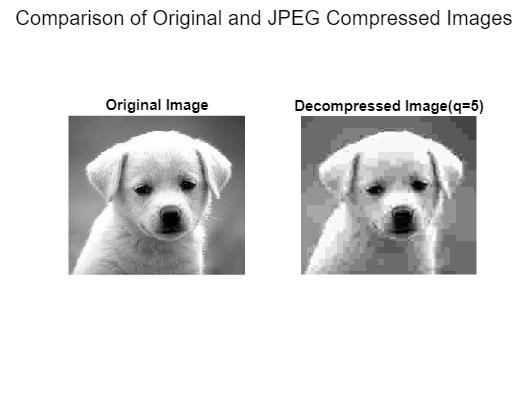

% Displaying the results

figure;

subplot(1, 2, 1);  
imshow(image);
title('Original Image');  

subplot(1, 2, 2);  
imshow(decompressed_im);
text = sprintf('Decompressed Image(q=%d)', q_value);
title(text);  

sgtitle('Comparison of Original and JPEG Compressed Images');